The main goal of this script is to:

- Generate a properly spectrogram of the acquired signal by the *Data Acquisiton Toolbox *and compare it to the one generated by PRAAT.

clc
clear

% Load both signals:
[audio_from_daq, Fs] = audioread("audio_1.wav");

% From the acquired signals compute the acquiring interval:
t_span = 0:1/Fs:((length(audio_from_daq) - 1) / Fs);

In PRAAT the user define the length in time of the spectrogram sliding window. To generate the most similar spectrogram, this notation will be used in this script:

window_time_span = .06; % In seconds

After loading the signal, the next step is to directly generate the spectrogram through the spectrogram() function.

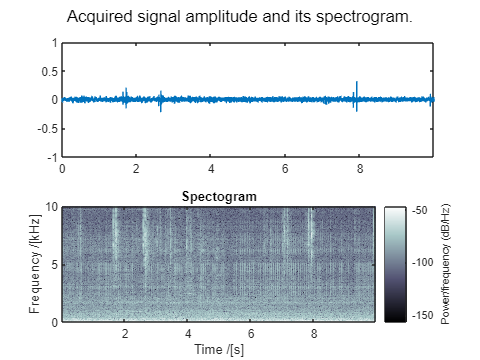

% Convert the window length in seconds to window lenght in number of
% samples:
L = window_time_span * Fs;
% Select the desired sliding window format:
window = hamming(L);

% Create a plot window:
figure()
sgtitle("Acquired signal amplitude and its spectrogram.")

% Plot the acquired signal amplitude:
subplot(2, 1, 1)
plot(t_span, audio_from_daq)
xlim([0, t_span(end)])
ylim([-1, 1])

% Plot the spectogram:
subplot(2, 1, 2)
colormap bone;
spectrogram(audio_from_daq, window, "yaxis",[],[],Fs);
title("Spectogram")
xlabel("Time /[s]")
ylabel("Frequency /[kHz]")
% Define the spectrogram frequency limits:
fmax = 10; % in kHz
fmin = 0; % in kHz
ylim([fmin, fmax])